# `Comparando los Datos`

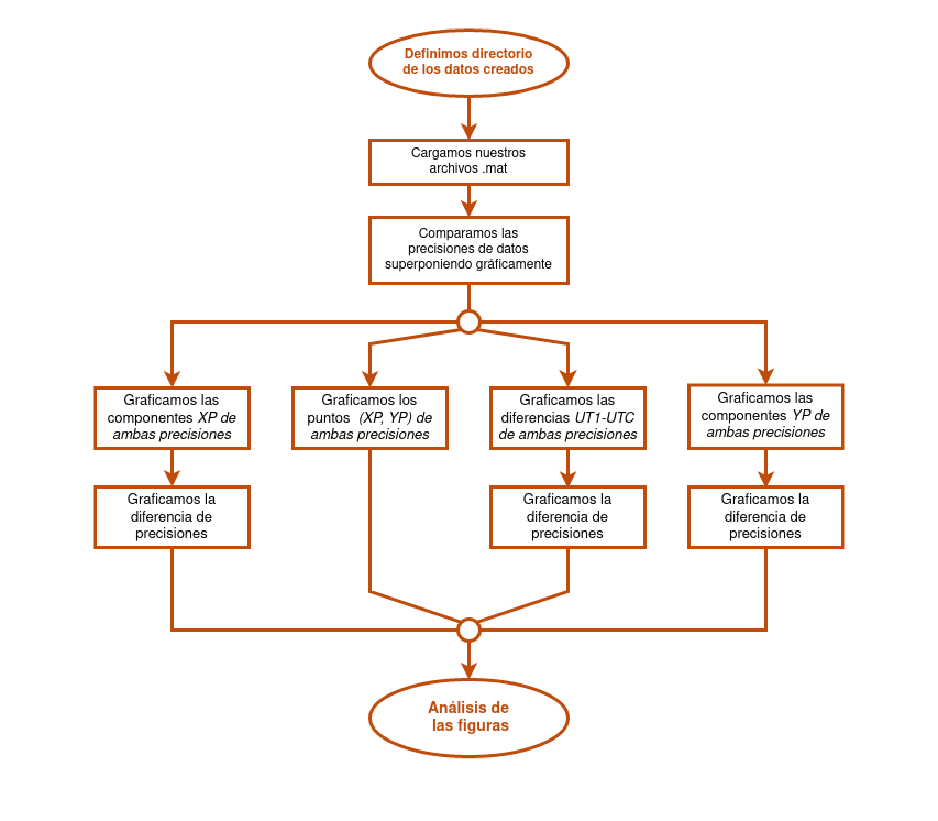

pathe_diag = '/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/DIAGRAMAS/';

[im, map, alpha] = imread([pathe_diag 'PR1-B3.png']);
figure; f = imshow(im);
set(f, 'AlphaData', alpha);

### `Cargando Datos`

En primer lugar cargamos los dos archivos donde guardamos las tablas de datos anteriormente creados.

directorio_raiz ='/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/'; 
directorio_datos = 'SALIDA/';
directorio_diag= 'DIAGRAMAS/';

pathe_diag=[directorio_raiz directorio_diag]

pathe_diag = '/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/DIAGRAMAS/'


load([directorio_raiz directorio_datos 'tablaImprecisos.mat'])
load([directorio_raiz directorio_datos 'tablaPrecisos.mat'])

size(tablaI)

ans =         6839           7


size(tablaP)

ans =         6839           7


### Polo X respecto al tiempo

En primer lugar comparamos las gráficas de la posición X del polo, y no apreciamos ninguna variación.

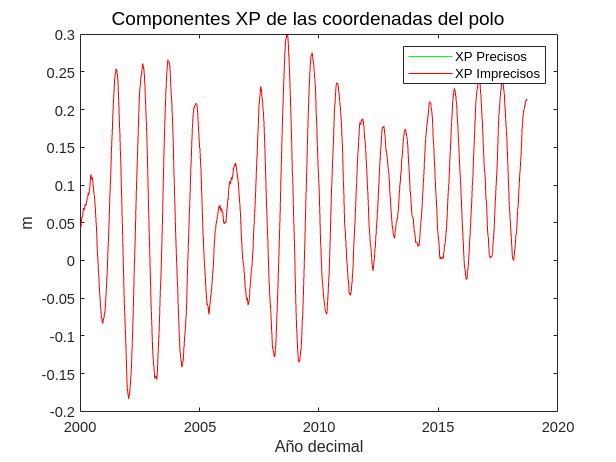

figure;
plot(tablaP.Fecha,tablaP.X,"green")
hold on
plot(tablaI.Fecha,tablaI.X,"red")
legend("XP Precisos","XP Imprecisos")
xlabel('Año decimal')
ylabel('m')
sgtitle('Componentes XP de las coordenadas del polo')
hold off

Sin embargo, si en la gráfica anterior nos acercamos lo suficiente, vemos pequeñas diferencias entre los datos.

Aquí la gráfica de la diferencia de los datos de XP precisos e imprecisos.

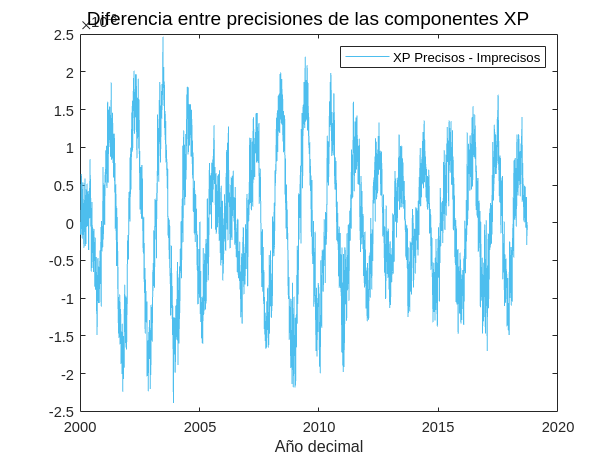

figure;
plot(tablaP.Fecha,tablaP.X-tablaI.X,'Color',[0.3010 0.7450 0.9330])
legend("XP Precisos - Imprecisos")
xlabel('Año decimal')
sgtitle('Diferencia entre precisiones de las componentes XP')
hold off

Se observa que la diferencia sigue el mismo patrón que los datos de la componente X.

### Polo Y respecto al tiempo

Lo siguiente es comparar la posición Y del polo, y como antes no observamos ninguna diferencia.

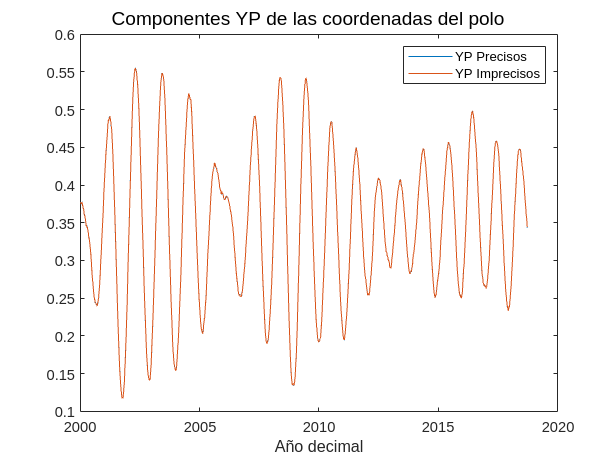

figure;
plot(tablaP.Fecha,tablaP.Y)
hold on
plot(tablaI.Fecha,tablaI.Y)
legend("YP Precisos","YP Imprecisos")
xlabel('Año decimal')
sgtitle('Componentes YP de las coordenadas del polo')
hold off

Como pasó anteriormente, si nos acercamos lo suficiente vemos pequeñas diferencias. 

Aquí la gráfica de la diferencia de los datos de YP precisos e imprecisos.

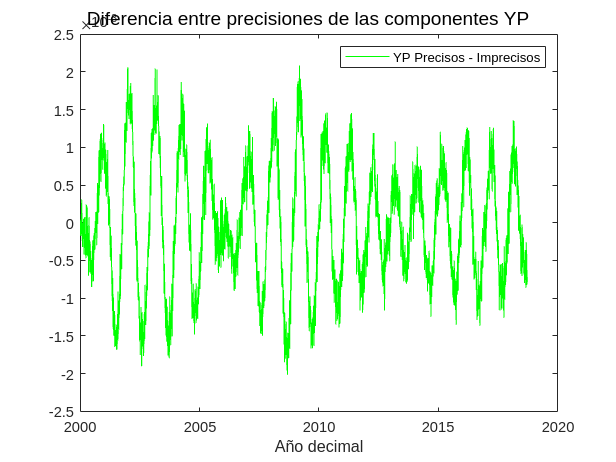

figure;
plot(tablaP.Fecha,tablaP.Y-tablaI.Y,"green")
legend("YP Precisos - Imprecisos")
xlabel('Año decimal')
sgtitle('Diferencia entre precisiones de las componentes YP')
hold off

Se observa que la diferencia sigue el mismo patrón que los datos de la componente X.

### **Posiciones del polo X e Y**

Ahora comparamos las posiciones X e Y del polo, no hay variación aparente.

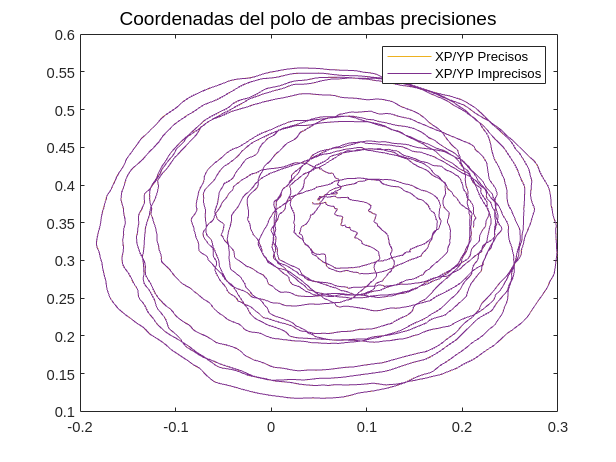

figure;
plot(tablaP.X,tablaP.Y,'Color',[0.9290 0.6940 0.1250])
hold on
plot(tablaI.X,tablaI.Y,'Color',[0.4940 0.1840 0.5560])
legend("XP/YP Precisos","XP/YP Imprecisos")
sgtitle('Coordenadas del polo de ambas precisiones')
hold off

Y como era de esperar, al unir las gráficas donde estén X e Y siguen habiendo diferencias al acercarnos lo suficiente.

### Variación UT1-UTC respecto del tiempo

En esta última gráfica la diferencia es más evidente, ya que en el inicio de ella hay un escalón de los datos precisos, así que podemos concluir que los otros datos no son tan acertados como los precisos.

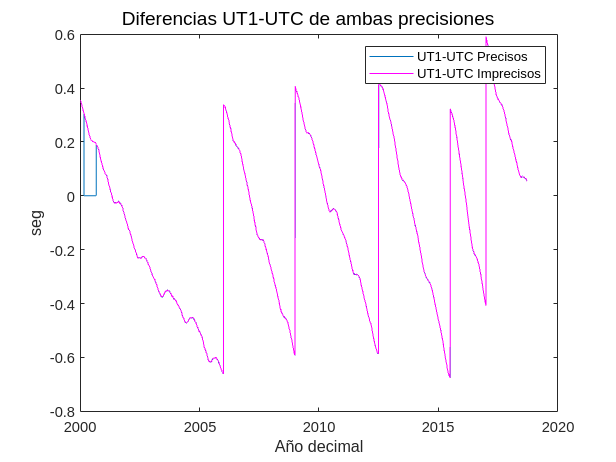

figure;
plot(tablaP.Fecha,tablaP.UT)
hold on
plot(tablaI.Fecha,tablaI.UT,"magenta")
legend("UT1-UTC Precisos","UT1-UTC Imprecisos")
xlabel('Año decimal')
ylabel('seg')
sgtitle('Diferencias UT1-UTC de ambas precisiones')
hold off

Aquí la gráfica de la diferencia de los datos de DTU1 precisos e imprecisos. Salvo el inicio, el resto están aproximados.

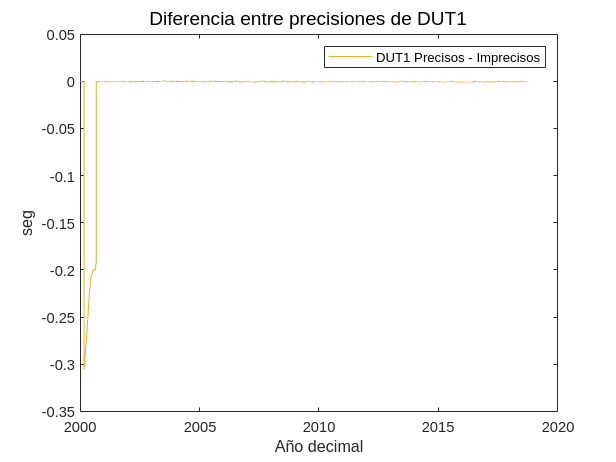

figure;
plot(tablaP.Fecha,tablaP.UT-tablaI.UT,'Color',[0.9290 0.6940 0.1250])
legend("DUT1 Precisos - Imprecisos ")
xlabel('Año decimal')
ylabel('seg')
sgtitle('Diferencia entre precisiones de DUT1')

*Adrián Fernández Tejada - Adrián Sánchez Loureiro*